folderPath = '/home/joshuarizzello/Documents/Repos/ProgettoASET';
addpath(genpath(folderPath))
clear all
close all
clc
D_and =[load("Miki_973_A_1.mat");
    load("MS_973_A_2.mat");
    load("FA_973_A_2.mat");
    load("JO_973_A_2.mat");
    load("MS_973_A_3.mat");
    load("FA_973_A_3.mat");
    load("JO_973_A_3.mat")];

D_rit = [load("FA_973_R_1.mat");
    load("MS_973_R_2.mat");
    load("FA_973_R_2.mat");
    load("JO_973_R_2.mat")
    load("MS_973_R_3.mat");
    load("FA_973_R_3.mat");
    load("JO_973_R_3.mat")];
D = [D_and; D_rit];

load("Fermate_973.mat");
%lat_true = stops_lat_rit;
%lon_true = stops_long_rit;
lat_true = stops_lat_and;
lon_true = stops_long_and;

lat = D(1).Position.latitude;
lon = D(1).Position.longitude;
speed = D(1).Position.speed;

basemapName = "offlineBusMap";
mbtilesFile = "MilanoMap.mbtiles";

addCustomBasemap(basemapName, mbtilesFile)

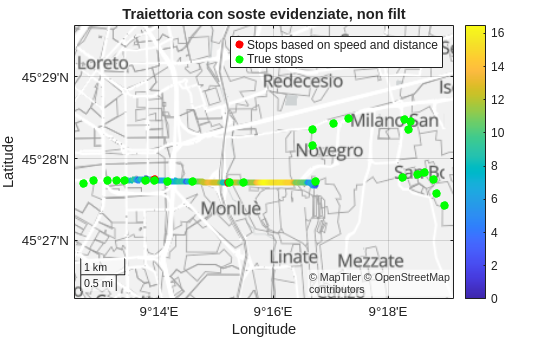


%Implementaato lo stesso metodo usato in data elaboration, per verificare anche graficamente il funzionametno (un log alla volta);
[Lat_And, Stops_Lat_And] = ndgrid(lat, lat_true);
[Lon_And, Stops_Lon_And] = ndgrid(lon, lon_true);
isStopped = deg2km(distance(Lat_And, Lon_And, Stops_Lat_And, Stops_Lon_And))*1000 < 15;
isStopped = any(isStopped, 2);
isStopped  = isStopped & (speed<0.6);



figure;
geobasemap offlineBusMap

geoscatter(lat(~isStopped), lon(~isStopped), 20, speed(~isStopped), 'filled')
hold on
s = geoscatter(lat(isStopped), lon(isStopped), 40, 'red', 'filled');
hold on
t = geoscatter(lat_true, lon_true, 40, 'green', 'filled');

colorbar
title('Traiettoria con soste evidenziate, non filt')
legend([s, t], {'Stops based on speed and distance', 'True stops'});
hold off


% for i=1:size(D_and,1)
%     lat = D(i).Position.latitude;
%     lon = D(i).Position.longitude;
%     speed = D(i).Position.speed;
%     %Implementaato lo stesso metodo usato in data elaboration, per verificare anche graficamente il funzionametno (un log alla volta);
%     [Lat_And, Stops_Lat_And] = ndgrid(lat, lat_true);
%     [Lon_And, Stops_Lon_And] = ndgrid(lon, lon_true);
%     isStopped = deg2km(distance(Lat_And, Lon_And, Stops_Lat_And, Stops_Lon_And))*1000 < 15;
%     isStopped = any(isStopped, 2);
%     isStopped  = isStopped & (speed<0.7);
% 
% 
%     geobasemap offlineBusMap
% 
%     geoscatter(lat(~isStopped), lon(~isStopped), 20, speed(~isStopped), 'filled')
%     hold on
%     s = geoscatter(lat(isStopped), lon(isStopped), 40, 'red', 'filled');
%     hold on
%     t = geoscatter(lat_true, lon_true, 40, 'green', 'filled');
%     hold on
%     z = geoscatter(lat_true1, lon_true1, 40, 'green', 'filled');
% 
%     colorbar
%     title('Traiettoria con soste evidenziate, non filt')
%     legend([s, t], {'Stops based on speed and distance', 'True stops'});
% end
% 
% hold off


N = 5;
b = ones(1, N) / N;
a = 1;
speed_f = filtfilt(b, a, speed); %media mobile senza introduzione di ritardo

isStopped = speed_f < 1.0;
figure;
geobasemap offlineBusMap

geoscatter(lat(~isStopped), lon(~isStopped), 20, speed(~isStopped), 'filled')
hold on
s = geoscatter(lat(isStopped), lon(isStopped), 40, 'red', 'filled');
t = geoscatter(lat_true, lon_true, 40, 'green', 'filled');

colorbar
title('Traiettoria con soste evidenziate, filt')
legend([s, t], {'Stops based on speed', 'True stops'});
speed_f = speed;
isStopped = speed_f < 0.7; %Confrontando i risultati la terrei non filtrata che non cambia e non perdiamo detagli

figure;
geobasemap offlineBusMap

geoscatter(lat(~isStopped), lon(~isStopped), 20, speed(~isStopped), 'filled')
hold on
s = geoscatter(lat(isStopped), lon(isStopped), 40, 'red', 'filled');
t = geoscatter(lat_true, lon_true, 40, 'green', 'filled');

colorbar
title('Traiettoria con soste evidenziate, non filt')
legend([s, t], {'Stops based on speed', 'True stops'});



% hold on
% clear Position
% clear Acceleration
% load("MS_973_R_3.mat");
% lat = Position.latitude;
% lon = Position.longitude;
% speed = Position.speed;
% geoscatter(lat, lon, 20, speed, 'filled')

% hold on
% clear Position
% clear Acceleration
% load("FA_973_R_3.mat");
% lat = Position.latitude;
% lon = Position.longitude;
% speed = Position.speed;
% geoscatter(lat, lon, 20, speed, 'filled')
% 
% hold on
% clear Position
% clear Acceleration
% load("JO_973_R_2.mat");
% lat = Position.latitude;
% lon = Position.longitude;
% speed = Position.speed;
% geoscatter(lat, lon, 20, speed, 'filled')
% 
% hold on
% clear Position
% clear Acceleration
% load("MS_973_R_2.mat");
% lat = Position.latitude;
% lon = Position.longitude;
% speed = Position.speed;
% geoscatter(lat, lon, 20, speed, 'filled')